### Choose test:

videoFolderPath = strcat('Z:\Projects\РФФИ-Норвегия\Данные\', ...
    'Экспериментальные данные в лаборатории\', ...
    'Droplet freezing facility data\Generating droplets\VIDEO_DATA');
% cropping folder
croppingFolderPath = strcat(videoFolderPath, '\', "cropping_data");
% data path
cropDataName = "cropping_video.csv";
dataPath = strcat(croppingFolderPath, '\', cropDataName);

strTestNum = "0238"

strTestNum = "0238"

testNum = uint16(str2double(strTestNum));
 

#### Open figure and range:

figName = strcat(strTestNum,"_EMD.fig")

figName = "0238_EMD.fig"

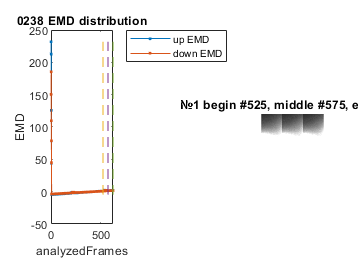

figPath = strcat(croppingFolderPath, '\',figName);

if exist(figPath,"file")
    figure(openfig(figPath))
else
    disp("Error! No such file.")
end

% READ TABLE

T = readtable(dataPath);
toShow = T.test == testNum;
disp(T(toShow,:));

    test    video_ranges
    ____    ____________

    238     {'525-626'} 



curCropRanges = T(toShow,:).video_ranges{1};
disp(curCropRanges);

525-626


#### Play video:

 
videoName = strcat(strTestNum,"_photron_avi.avi")
videoPath = strcat(videoFolderPath, '\', videoName);

if exist(videoPath,"file")
    % playing videofile
    implay(videoPath);
else
    disp("Error! No such file.")
end

### **NEW AUTO CROPPING**

#### Load video from Workspace:

videoName = strcat(strTestNum,"_photron_avi.avi")
if exist('allVideoNames', 'var')
    index = find([allVideoNames{:}] == videoName);
    if index > 0
        obj = allObj{index};
        video = allVideos{index};
        frameRange = [1 obj.NumFrames];
        disp('Video uploaded from workspace')
    else
        disp("Error! No such test in workspace")
    end
else
    disp("Error! No videos in workspace")
end

 

#### Load video from disk:

frameRange =[6 inf];

 
videoName = strcat(strTestNum,"_photron_avi.avi")

videoName = "0238_photron_avi.avi"

videoPath = strcat(videoFolderPath, '\', videoName);

% create video object
obj = VideoReader(videoPath);

% total frame count
allFramesCount = obj.NumFrames;

% checking the end of the frameRange
if allFramesCount < frameRange(2)
    frameRange(2) = allFramesCount;
end

disp('Real frame range:');

Real frame range:


disp(frameRange);

     6   626




% Import the video file
video = obj.read(frameRange);
disp("Video uploaded from drive");

Video uploaded from drive


#### ANALYZING VIDEO

#### Analyzing settings

Chose **Intensity threshold** *(from 1 to 256; what intensity in diffImage is a threshold for droplet appearing)*, 

**scale koeficient** (*for increasing peaks high*), 

**frame limit** *(count of frames, exceeding of which without EMD-changing means new droplets),  *

**smoothSpan** - span of the moving average (1 ...).

**polyOrder** - order of polinominal fitting.

**baseSide** - side for finding count of crops.


threshold =  40

threshold = 40

scaleKoef = [4 0]

scaleKoef =      4     0


frameLimit = 60

frameLimit = 60

smoothSpan = 5

smoothSpan = 5

% SET order of polinominal fit
upPolyOrder = 0

upPolyOrder = 0

downPolyOrder = 0

downPolyOrder = 0

polyOrder = [upPolyOrder downPolyOrder];
% SET Threshold value of detrending signal [up down]
quantileThreshold  = [1.0 0.95]

quantileThreshold =     1.0000    0.9500


baseSide = "down"

baseSide = "down"

% SET BASE SIDE (1 - up; 2 - down)
switch baseSide
    case "up"
        baseFrameSide = 1;
    case "down"
        baseFrameSide = 2;
    otherwise 
        baseFrameSide = 2;
end

% changing EMD-levels
upScaleKoef = scaleKoef(1); 
downScaleKoef = scaleKoef(2);

% SET Quantile value (0...1)
maxEMDQuantileValue = [0.90 0.90];
maxSecDifQuantileValue = [0.5 0.5];

% SET Max distance (in UpDownKoef*frameLimit between peaks)
UpDownKoef = 3;

#### Auto analyze video:

Before clicking "ANALYZE", setup "Analyzing settings"

 

currentVideoName = videoName;
disp(strcat("ANALYZING: ", currentVideoName));

ANALYZING: 0238_photron_avi.avi


% ANALYZE!
[selectedFrames, analyzedFrames, EMD,...
    templateImg] = cropVideoEMD(obj, video, frameRange, threshold,...
    upScaleKoef, downScaleKoef, frameLimit, smoothSpan, polyOrder,...
    baseFrameSide, maxEMDQuantileValue, maxSecDifQuantileValue,...
    UpDownKoef, quantileThreshold);

Count of detected crops: 2


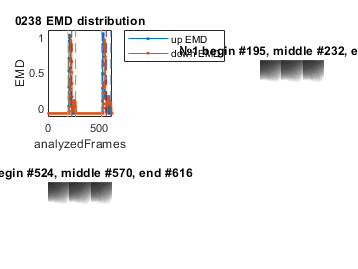


% DISPLAY EMD-Values and images
dispFrames(selectedFrames, analyzedFrames, EMD, video, ...
     testNum);

%Create ranges of crop in string format
cropRanges = cropRanges2str(selectedFrames);
if exist('curCropRanges', 'var')
    disp("Last ranges:");
    disp(curCropRanges);
end

Last ranges:


525-626


disp("Recieved ranges:");

Recieved ranges:


disp(cropRanges);

195-270,524-616


### **SAVE CROPPED RANGES AND FIGURE**

If **"Cropped ranges"** are not satisfactory, you can edit them before saving to dataframe. 

If it's necessary, you can use "Manual video analyzing" below and click **"Save"**.

flagRange=false;
editCropRange="165-298,489-596";
flagFig=true;
 
if flagRange
    savedCropRanges = editCropRange;
else
    savedCropRanges = cropRanges;
end

if flagFig
    % SAVE EMD-Values and images of cropped video as fig.
    figPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum), ...
        "_EMD",".fig");
    savefig(figPath);
    disp("Last figure was saved");
    % SAVE Template
    templPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum),...
        "_template",".jpg");
    imwrite(templateImg,templPath)
    disp("Last template was saved");
end

Last figure was saved


Last template was saved


% READ TABLE
T = readtable(dataPath);

% delete previos ranges
toDelete = T.test == testNum;
T(toDelete,:) = [];

% add new value
savedRow = {testNum,savedCropRanges};
T = [T;savedRow];

% WRITE TABLE
writetable(T,dataPath);

disp('Saved row:')

Saved row:


disp(savedRow)

    {[238]}    {'195-270,524-616'}



### **MANUAL VIDEO-EMD ANALYZING**

#### Analyzing settings

Chose **frame range** *ex.:[1 inf], *

**intensity threshold** *(from 1 to 256; what intensity in diffImage is a threshold for droplet appearing)*, 

**scale koeficient** (*for increasing peaks high*)

manFrameRange =[1 150]
threshold =  50
scaleKoef = [10 0]

% total frame count
allFramesCount = obj.NumFrames;

% checking the end of the frameRange
if allFramesCount < manFrameRange(2)
    manFrameRange(2) = allFramesCount;
end

disp('Real frame range:');
disp(manFrameRange);

% changing EMD-levels
upScaleKoef = scaleKoef(1); 
downScaleKoef = scaleKoef(2);

#### Manual analyzing video:

**Before clicking "ANALYZE"**, setup "Analyzing settings" above

 
[manAnalyzedFrames, manEMD, histArray, imArray, imDifArray] = ...
    analyzeVideoEMD(obj, video, manFrameRange, threshold,...
    upScaleKoef, downScaleKoef);
disp("EMD-values recieved!");

#### INTERACTIVE PLOTTING

Manual search for the maxFactor values

ymax = max(max(manEMD))+0.05;
tiledlayout(3,2,"TileSpacing","tight");

firstFrame = manAnalyzedFrames(1);
lastFrame = manAnalyzedFrames(length(manAnalyzedFrames));

nexttile(1,[1 2]);
plot(manAnalyzedFrames,manEMD(:,2), ...
    manAnalyzedFrames,manEMD(:,3),'Marker','.')

labels = cell(2,1);
labels{1} = "up EMD";
labels{2} = "down EMD";

#### Change frame number.

frameNum =82
hold on
plot([frameNum frameNum],[0 ymax],'LineStyle',"-",'Marker',"none")

% Add xlabel, ylabel, title
xlabel('analyzedFrames');
ylabel('EMD');
title(strcat("Test ", sprintf('%04u',testNum),' EMD distribution'));
legend(labels,'Location','northeastoutside');

nexttile(3, [2 1]);
montage({imArray{1}(:,:,frameNum), imDifArray{1}(:,:,frameNum)});
title({strcat('Frame #',string(frameNum)) ,'orig img | img-template diff'})

nexttile(4, [1 1]);
ax = gca;
% Create histogram of templateHist and grayscale
% Create bar of templateHist
bar(ax, histArray(:,frameNum,2), 1); 

% Add ylabel, title, and legend
ax.YScale = 'log';
ylabel('Intensity')
title(strcat('Up img-template diff hist'))

nexttile(6, [1 1]);
ax = gca;
% Create histogram of templateHist and grayscale
% Create bar of templateHist
bar(ax, histArray(:,frameNum,3), 1); 

% Add ylabel, title, and legend
ax.YScale = 'log';
ylabel('Intensity')
title(strcat('Down img-template diff hist'))